%wind导入历史行情序列
w = windmatlab;
begintime='20210101';     %时间序列开始日
endtime='20211231';       %时间序列结束日
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('601166.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =    84.7522
   81.3448
   85.0972
   86.6930
   87.6419
   88.4614
   89.9279
   91.0061
   92.0844
   97.9502


w_wsd_codes = 1×1 cell 数组
    {'601166.SH'}


w_wsd_fields = 1×1 cell 数组
    {'CLOSE'}


w_wsd_times =       738160
      738161
      738162
      738163
      738164
      738167
      738168
      738169
      738170
      738171


w_wsd_errorid = 0

SA = [w_wsd_times,w_wsd_data]

SA = 	1.0e+05 *

    7.3816    0.0008
    7.3816    0.0008
    7.3816    0.0009
    7.3816    0.0009
    7.3816    0.0009
    7.3817    0.0009
    7.3817    0.0009
    7.3817    0.0009
    7.3817    0.0009
    7.3817    0.0010


clearvars -except SA

%数据清洗
SA = rmmissing(SA);    %清除空值
time = datetime(SA(:,1),'ConvertFrom','datenum');   %将数据第一列转为datetime数组并定义为time
prices = SA(:,2);
T = timetable(time,prices);
LogReturns = diff(log(prices));
clearvars -except  LogReturns T prices SA

econometricModeler

%模型模拟
md1 = EGARCH

md1 =   egarch - 属性:

     Description: "EGARCH(0,0) Conditional Variance Model (Gaussian Distribution)"
    Distribution: Name = "Gaussian"
               P: 0
               Q: 0
        Constant: -7.67752
           GARCH: {}
            ARCH: {}
        Leverage: {}
          Offset: 0

V0 = infer(md1,LogReturns);
[V,Y] = simulate(md1,252,'NumPaths',10000,'E0',LogReturns,'V0',V0)

V = 	1.0e+-3 *

    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631
    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631    0.4631   

Y =     0.0116    0.0395   -0.0486    0.0186    0.0069   -0.0281   -0.0093    0.0074    0.0770    0.0596   -0.0290    0.0653    0.0156   -0.0014    0.0154   -0.0044   -0.0027    0.0321    0.0303    0.0305    0.0145   -0.0260    0.0154    0.0351    0.0105    0.0223    0.0156   -0.0065    0.0063   -0.0169    0.0191   -0.0247   -0.0230   -0.0174   -0.0634    0.0310    0.0070   -0.0162    0.0295   -0.0368   -0.0022   -0.0052    0.0069    0.0067   -0.0186   -0.0006   -0.0035    0.0135    0.0235    0.0239
   -0.0413   -0.0028   -0.0165    0.0514    0.0017    0.0081    0.0085   -0.0024   -0.0394    0.0450    0.0077   -0.0171   -0.0049    0.0343    0.0033    0.0038   -0.0073   -0.0328   -0.0153   -0.0186    0.0015    0.0033   -0.0039    0.0157   -0.0075    0.0050   -0.0187   -0.0211   -0.0063    0.0177    0.0042    0.0064   -0.0153   -0.0148    0.0123    0.0096   -0.0285   -0.0323    0.0219   -0.0006   -0.0035    0.0082   -0.0023    0.0046    0.0101   -0.0348    0.0003   -0.0008    0.0087    0

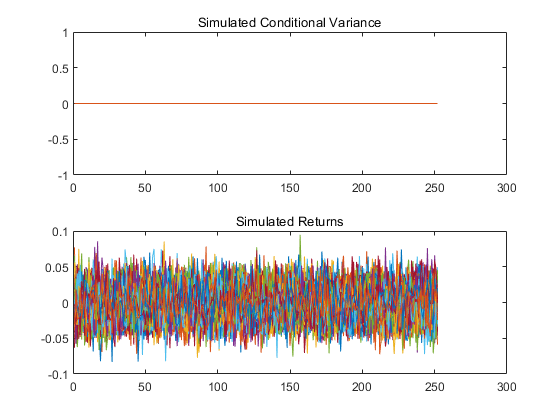

%画出10个路径上的模拟值
figure
subplot(2,1,1)
plot(V(:,1:100))
title('Simulated Conditional Variance')
subplot(2,1,2)
plot(Y(:,1:100))
title('Simulated Returns')

%计算预测波动率和历史波动率
tradingDays = 252;
LogReturns = rmmissing(LogReturns);
Fvol = mean(std(Y))*sqrt(tradingDays);
Hvol1Y = std(LogReturns)*sqrt(tradingDays);
disp(['Forecasted 1-year volatility = ' num2str(Fvol*100,4) '%'])

Forecasted 1-year volatility = 34.13%


disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])

Historical 1-year volatility = 34.23%
